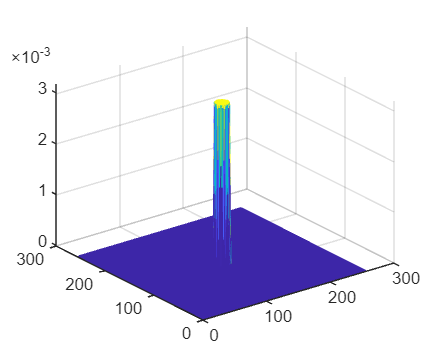

%PSF and MTF
h=fspecial('disk',10);
sum(sum(h));
f=zeros(256);
sz=size(h);
f((128-int16(sz(1)/2)): (127+int16(sz(1)/2)-1),(128-int16(sz(2)/2)): (127+int16(sz(2)/2)-1))=h;
figure(1);
imshow(f,[]);

figure(2);
mesh(f);

%MTF de h
figure(1);
H=fft2(h);
mesh(fftshift(abs(H)));
isz=size(H);
MTF=abs(H(1:int16(isz(1)/2),1));
figure(3);
plot(MTF);

%Real MTF at image
figure(2);
H=fft2(f);
mesh(fftshift(abs(H)));

%PSF and MTF
f=zeros(512);
cx=int16(512/2);
cy=int16(512/2);
sz=size(h);
f((cy-int16(sz(1)/2)+1):(cy+int16(sz(1)/2)-1), (cx-int16(sz(2)/2)+1):(cx+int16(sz(2)/2)-1))=h;
figure(1);
imshow(f,[]);
figure(2);
mesh(f);

%MTF de h
figure(1);
H=fft2(h);
mesh(fftshift(abs(H)));
figure(3);
imshow(h,[]);

%Real MTF at image
figure(2);
H=fft2(f);
mesh(fftshift(abs(H)));